# Análise de espaço de estados

clear all;
close all;
clc;


## Definindo o modelo não linear


% Definido em um bloco Simulink - SIR

beta = 1e-3;
r = 1e-1;

S0 = 499;
I0 = 1;
R0 = 0;

options = simset('solver','ode45','MaxStep',0.01,'InitialStep',0.01,'ReturnWorkspaceOutputs', 'on');
y = sim('SIRmodel',100,options);


## Variáveis

I = y.logsout{1}.Values.Data; % Saída I
S = y.logsout{2}.Values.Data; % Saída S
R = y.logsout{3}.Values.Data; % Saída R
t = y.tout;


## Visualiação de simulação do modelo

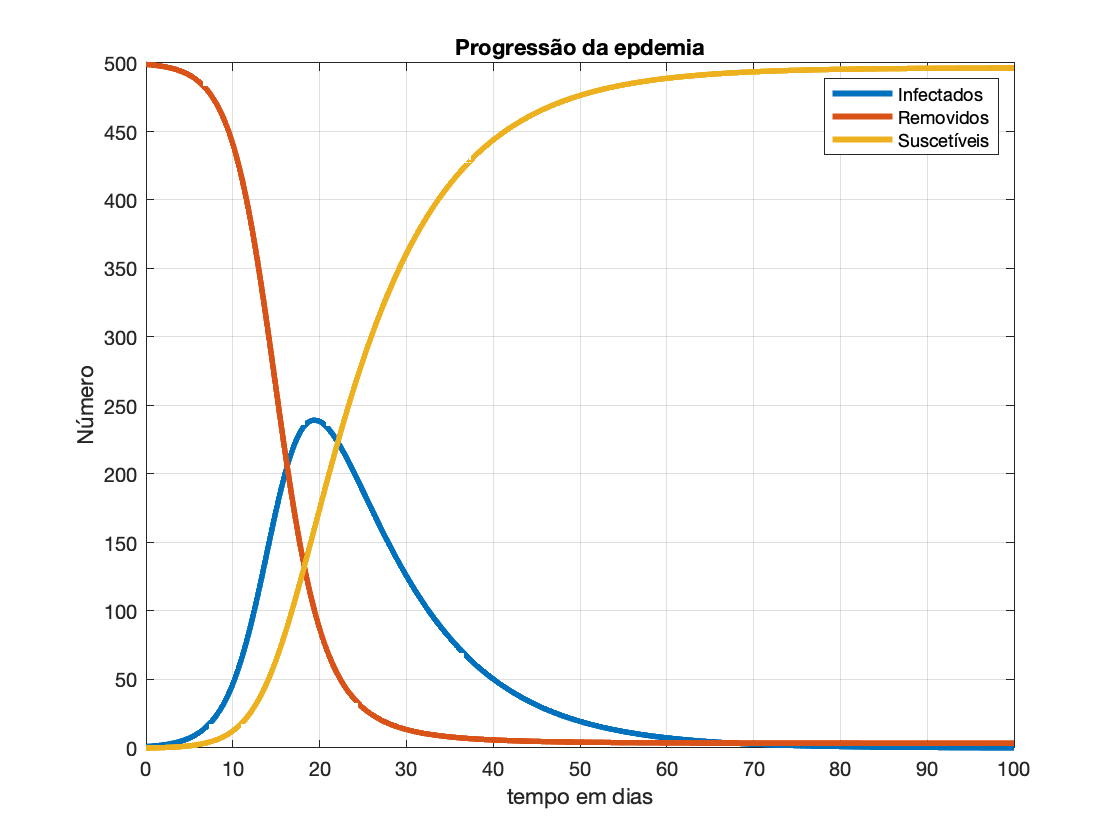

figure()
plot(t,I,t,R,t,S,'Linewidth',3);
grid;
legend('Infectados','Removidos','Suscetíveis');
xlabel('tempo em dias')
ylabel('Número')
title('Progressão da epdemia')

## Condições de linearização


beta0  = 1e-3;
r0     = 1e-1;       


## Linearizar o modelo


[A,B,C,D] = linmod('SIRsim')

A =    -0.0010   -0.4990         0
    0.0010    0.3990         0
         0    0.1000         0


B =   -499     0
   499    -1
     0     1


C =      1     0     0
     0     1     0
     0     0     1


D =      0     0
     0     0
     0     0


## Comparação entre o não linear e o linear

x0 = [S0;I0;R0];

options = simset('solver','ode45','MaxStep',0.01,'InitialStep',0.01,'ReturnWorkspaceOutputs', 'on');
y = sim('SIRComp',2,options);

%% Outro ponto de linearização


## Propriedades do modelo linear

% Auto valores

% [V,D,W] = eig(A) also produces a full matrix W whose columns are the
%     corresponding left eigenvectors so that W'*A = D*W'.

% Auto vetores - diganalização

% [V,D,W] = eig(A) also produces a full matrix W whose columns are the
%     corresponding left eigenvectors so that W'*A = D*W'.

% Observabilidade

% OB = obsv(A,C) returns the observability matrix [C; CA; CA^2 ...]

% Controlabilidade

% CO = ctrb(A,B) returns the controllability matrix [B AB A^2B ...].
    
% Matriz de transferência

% ss2tf  State-space to transfer function conversion.
%     [NUM,DEN] = ss2tf(A,B,C,D,iu)  calculates the transfer function:

[V,D,W] = eig(A)

V =          0   -0.7718    0.7080
         0    0.6167   -0.0018
    1.0000    0.1551   -0.7062


D =          0         0         0
         0    0.3977         0
         0         0    0.0003


W =     0.5774    0.0025    0.6243
    0.5774    1.0000    0.7812
    0.5774         0         0


OB = obsv(A,C) % é o estado se manifestando na saída

OB =     1.0000         0         0
         0    1.0000         0
         0         0    1.0000
   -0.0010   -0.4990         0
    0.0010    0.3990         0
         0    0.1000         0
   -0.0005   -0.1986         0
    0.0004    0.1587         0
    0.0001    0.0399         0


rank(OB)   % sistema é observável

ans = 3

CO = ctrb(A,B)  % entrada se manifestando no estado

CO =  -499.0000         0 -248.5020    0.4990  -98.8539    0.1986
  499.0000   -1.0000  198.6020   -0.3990   78.9937   -0.1587
         0    1.0000   49.9000   -0.1000   19.8602   -0.0399


rank(CO)

ans = 2

## Linearizando em outro ponto

S0 = S(2600);
R0 = R(2600);
I0 = I(2600);

[A,B,C,D] = linmod('SIRsim')

A =    -0.1744   -0.3010         0
    0.1744    0.2010         0
         0    0.1000         0


B = 	1.0e+04 *

   -5.2494         0
    5.2494   -0.0174
         0    0.0174


C =      1     0     0
     0     1     0
     0     0     1


D =      0     0
     0     0
     0     0



[V,D,W] = eig(A)

V =    0.0000 + 0.0000i   0.7233 + 0.0000i   0.7233 + 0.0000i
   0.0000 + 0.0000i  -0.4510 - 0.3157i  -0.4510 + 0.3157i
   1.0000 + 0.0000i  -0.2723 + 0.3157i  -0.2723 - 0.3157i


D =    0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0133 + 0.1314i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0133 - 0.1314i


W =    0.5774 + 0.0000i   0.4962 + 0.3473i   0.4962 - 0.3473i
   0.5774 + 0.0000i   0.7957 + 0.0000i   0.7957 + 0.0000i
   0.5774 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i



OB = obsv(A,C);
rank(OB)

ans = 3

CO = ctrb(A,B);
rank(CO)

ans = 2

## Analisando um simulador de Infectados

S0 = S(2600);
R0 = R(2600);
I0 = I(2600);

[A,B,C,D] = linmod('Isim')

A =     0.2010    0.1744
   -0.3010   -0.1744


B = 	1.0e+04 *

    5.2494   -0.0174
   -5.2494         0


C =      1     0


D =      0     0


[V,D,W] = eig(A)

V =   -0.4962 - 0.3473i  -0.4962 + 0.3473i
   0.7957 + 0.0000i   0.7957 + 0.0000i


D =    0.0133 + 0.1314i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0133 - 0.1314i


W =    0.7957 + 0.0000i   0.7957 + 0.0000i
   0.4962 + 0.3473i   0.4962 - 0.3473i



OB = obsv(A,C)

OB =     1.0000         0
    0.2010    0.1744


rank(OB)

ans = 2

CO = ctrb(A,B)

CO = 	1.0e+04 *

    5.2494   -0.0174    0.1398   -0.0035
   -5.2494         0   -0.6647    0.0052


rank(CO)

ans = 2

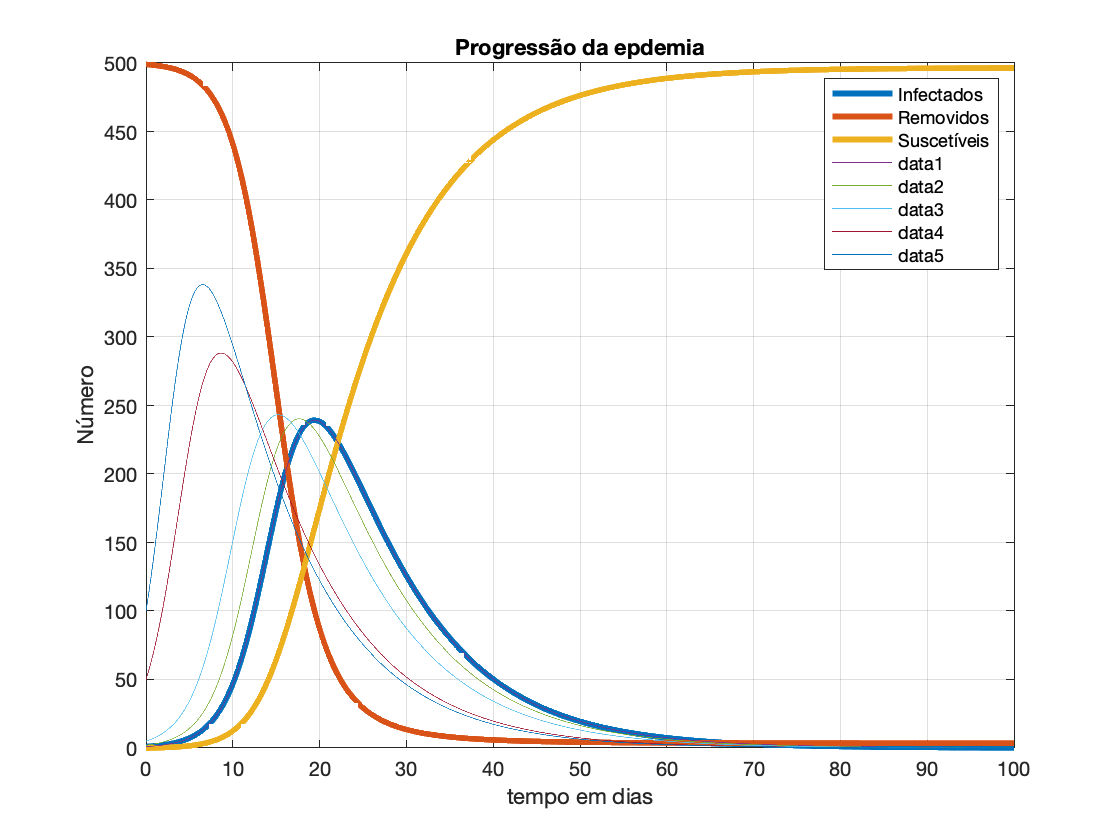

beta = 1e-3;
r = 1e-1;

S0 = 499;
Iini = [1 2 5 50 100];
R0 = 0;

for k = 1:5

I0 = Iini(k);

options = simset('solver','ode45','MaxStep',0.01,'InitialStep',0.01,'ReturnWorkspaceOutputs', 'on');
y = sim('SIRmodel',100,options);

I = y.logsout{1}.Values.Data; % Saída I
S = y.logsout{2}.Values.Data; % Saída S
R = y.logsout{3}.Values.Data; % Saída R
t = y.tout;

if k==1
    hold on;
end

plot(t,I)

end